# Problem Set 5

## Part A

num_trials = length(Kinematics.Trials);
X = cat(1, Kinematics.Trials{:});
[coeff, score, latent, ~, explained] = pca(X);
% coeff (22x22), score (trials concatx22), latent (22x1), explained (22x1)
variance_normalized = explained / 100;
cumulative_variance = cumsum(variance_normalized);
num_pcs = length(variance_normalized);
fprintf('\n--- Variance Explained ---\n');


--- Variance Explained ---


fprintf('PC1 : %5.2f%%\n', explained(1));

PC1 : 48.18%


fprintf('PC1 + PC2 : %5.2f%%\n', sum(explained(1:2)));

PC1 + PC2 : 70.28%


fprintf('PC1–PC3 : %5.2f%%\n', sum(explained(1:3)));

PC1–PC3 : 77.45%


num_pcs_90 = find(cumulative_variance >= 0.9, 1);
fprintf('PCs for 90%% variance: %d  (cumulative variance explained = %.2f%%)\n', num_pcs_90, cumulative_variance(num_pcs_90)*100);

PCs for 90% variance: 7  (cumulative variance explained = 92.19%)


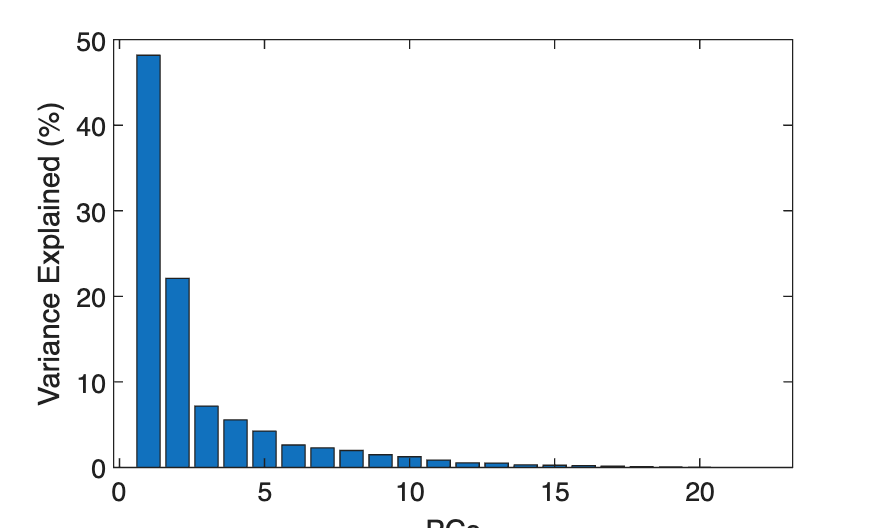


figure;
bar(1:num_pcs, variance_normalized*100)
xlabel('PCs')
ylabel('Variance Explained (%)')

## Part B

trial = 1;
cond = 'wr_flexion_l';
cond_ind = find(strcmp(Kinematics.ColumnNames, cond));

% pca on all the data again like the problem set says
X = cat(1, Kinematics.Trials{:});
[coeff, score, latent, ~, explained] = pca(X);

mu = mean(X, 1);
trial_center = Kinematics.Trials{1} - mu;
scores = trial_center * coeff;
y_true = Kinematics.Trials{1}(:,cond_ind);
pc_groups = {1, 2, 3, 22};
labels = {'PC1', 'PC1 + PC2', 'PC1 + PC2 + PC3', 'All PCs'};
reconstructions = cell(1, 4);
r2_values = zeros(1, 4);

for i = 1:4
    k = pc_groups{i};
    A = [scores(:, 1:k), ones(length(y_true), 1)];
    beta = A \ y_true; 
    y_hat = A * beta;
    
    reconstructions{i} = y_hat; 
    ss_res = sum((y_true - y_hat).^2);
    ss_tot = sum((y_true - mean(y_true)).^2);
    r2_values(i) = 1 - ss_res / ss_tot;
    fprintf('%s  ->  R² = %.4f\n', labels{i}, r2_values(i));
end

PC1  ->  R² = 0.1717
PC1 + PC2  ->  R² = 0.7715
PC1 + PC2 + PC3  ->  R² = 0.9916
All PCs  ->  R² = 1.0000



figure;
time_vec = 1:length(y_true);

for i = 1:4
    subplot(2, 2, i);
    plot(time_vec, y_true, 'k-')
    hold on
    plot(time_vec, reconstructions{i}, 'Color', 'r')
    title(labels{i})
    xlabel('Timesteps')
    ylabel('Wrist flexion angle')
end


PC1 captures 48% of the variance of all the joints. Wrist flexion does not align well with this shared pattern of variance between all the joints, which leads to the low R^2 value of 0.17. PC1 and PC2 together capture 77% of the variance, which fits to the wrist flexion beter. PC1, PC2, and PC3, together capture almost 100 percent of the variance. The 0.99 R^2 value shows that wrist flexion can be seen as a linear combination of the first three joint coordination patterns determined by these principle components. When we use all PCs, we get an R^2 of 1. This is because using all PCs is equivalent to using the original data, which is why we have perfect reconstruction quality. 

## Part C

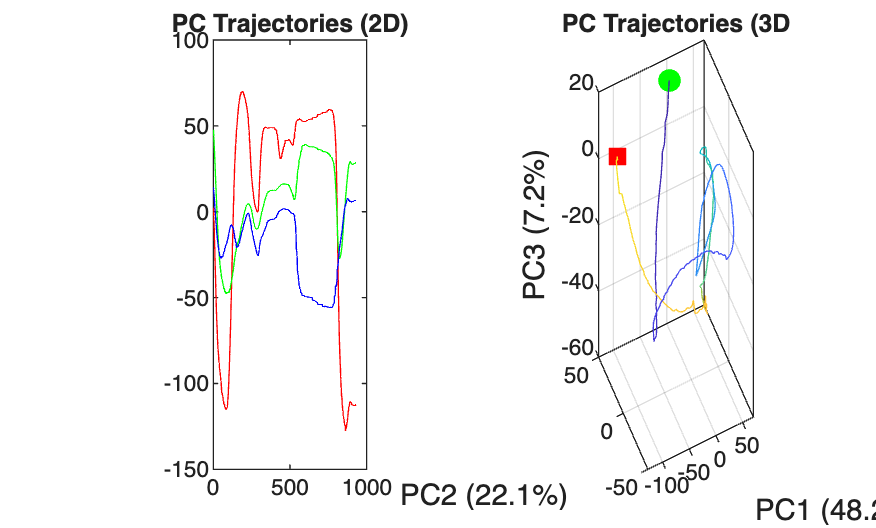

X = cat(1, Kinematics.Trials{:});
[coeff, score, latent, ~, explained] = pca(X);
mu = mean(X, 1);
time_vec = (1:size(Kinematics.Trials{1}, 1));
scores = (Kinematics.Trials{1} - mu) * coeff;

figure;
subplot(1, 2, 1);
cmap = colormap(gca, hsv(3));
for k = 1:3
    plot(time_vec, scores(:, k), 'Color', cmap(k, :))
    hold on
end
title('PC Trajectories (2D)')

subplot(1, 2, 2);
cmap = colormap(gca, parula(size(Kinematics.Trials{1}, 1)));
for i = 1:size(Kinematics.Trials{1}, 1)-1
    plot3(scores(i:i+1, 1), scores(i:i+1, 2), scores(i:i+1, 3), 'Color', cmap(i,:))
    hold on
end
view([-25, 25])
plot3(scores(1,1),   scores(1,2),   scores(1,3),   'go', ...
      'MarkerSize',8, 'MarkerFaceColor','g', 'DisplayName','Start');
plot3(scores(end,1), scores(end,2), scores(end,3), 'rs', ...
      'MarkerSize',8, 'MarkerFaceColor','r', 'DisplayName','End');
xlabel(sprintf('PC1 (%.1f%%)', explained(1)), 'FontSize', 11);
ylabel(sprintf('PC2 (%.1f%%)', explained(2)), 'FontSize', 11);
zlabel(sprintf('PC3 (%.1f%%)', explained(3)), 'FontSize', 11);
title('PC Trajectories (3D')
grid on; 
box on;

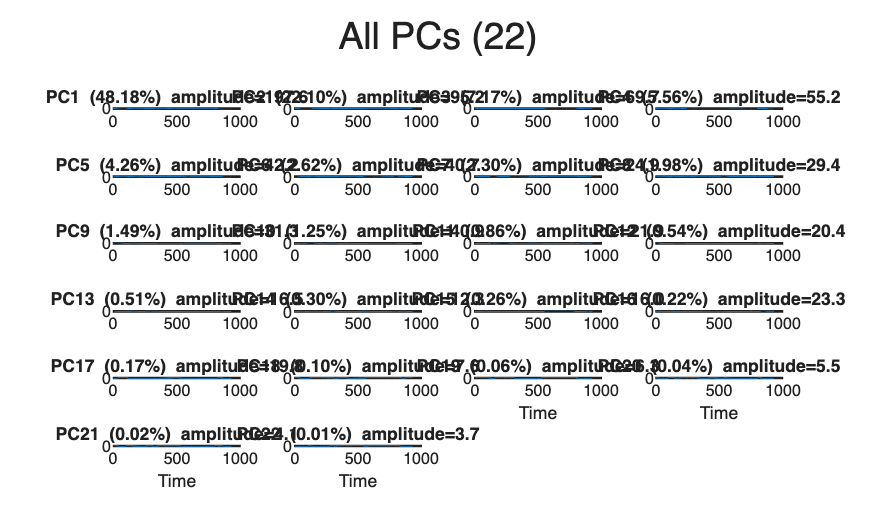



figure;
for k = 1:22
    subplot(6, 4, k);
    plot(time_vec, scores(:, k));
    amp = max(scores(:,k)) - min(scores(:,k));
    title(sprintf('PC%d  (%.2f%%)  amplitude=%.1f', k, explained(k), amp));
    if k > 18
        xlabel('Time','FontSize',7); 
    end
    if mod(k-1,4)==0
        ylabel('Score','FontSize',7); 
    end
    set(gca,'FontSize',6);
end

sgtitle('All PCs (22)');

As the projections decrease in variance, the amplitudes become smaller and the frequencies become greater. The signals become faster oscillating and more noisy. This is because each successive principle component captures less variance than the previous one. The earlier PCs will therefore capture the lower frequency and lower noise components, while the later PCs will get the more noisy data. 

## Part 1

% Part A
nConditions = length(R);
nUnits  = length(R(1).unit);
startTime = -150;
endTime = 500;
binSize = 10;
bin_edges = (startTime:binSize:endTime);
nTimeBins = length(bin_edges) - 1; 
spikeCounts = zeros(nTimeBins, nConditions, nUnits);

for trial = 1:nConditions
    moveOnsetTime = R(trial).moveOnsetTime;
    for unit = 1:nUnits
        spikeTime = R(trial).unit(unit).spikeTimes;
        if isempty(spikeTime)
            continue
        end
        spikeTimeLocked = spikeTime - moveOnsetTime;
        spikeCounts(:, trial, unit) = histcounts(spikeTimeLocked, bin_edges);
    end
end

% Part B
sd_ms = 40;
sd_bins = sd_ms / binSize;
spike_counts_smooth = gaussFilt1(spikeCounts, sd_bins, 1);

% Part C
conditionIDs = [R.conditionID];
conditions = unique(conditionIDs);
nConditions = length(conditions);
mean_firing_rate = zeros(nTimeBins, nConditions, nUnits);

for c = 1:nConditions
    trial_idx = conditionIDs == conditions(c);
    mean_firing_rate(:, c, :) = mean(spike_counts_smooth(:, trial_idx, :), 2) ...
                       * (1000 / binSize);
end

fprintf('mean_fr size: %d x %d x %d  (spikes/s)\n', size(mean_firing_rate));

mean_fr size: 65 x 72 x 158  (spikes/s)


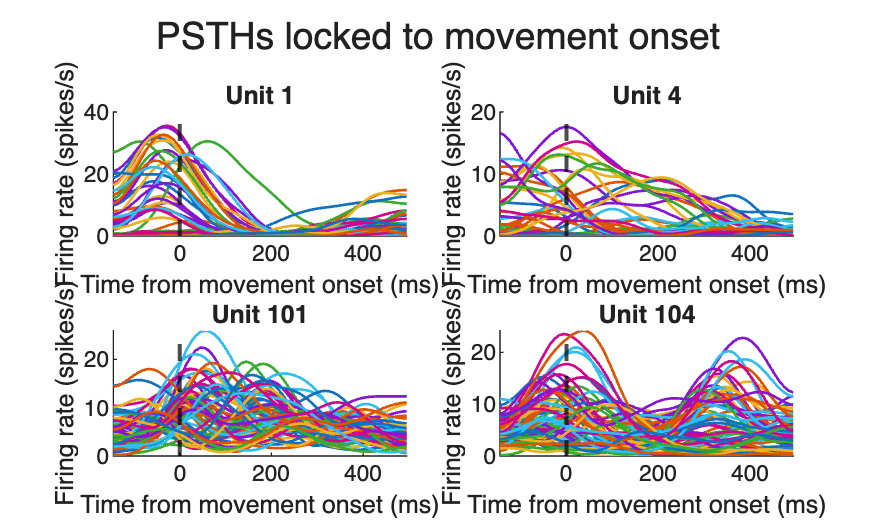

units_to_plot = [1, 4, 101, 104];
nPlotUnits    = length(units_to_plot);

figure;
bin_centers = bin_edges(1:end-1) + binSize/2; 

for p = 1:nPlotUnits
    u = units_to_plot(p);

    subplot(2, 2, p);
    hold on;

    cmap = lines(nConditions);
    for c = 1:nConditions
        plot(bin_centers, mean_firing_rate(:, c, u), 'Color', cmap(c, :), 'LineWidth', 1);
    end

    xline(0, 'k--', 'LineWidth', 1.5); 
    xlabel('Time from movement onset (ms)');
    ylabel('Firing rate (spikes/s)');
    title(sprintf('Unit %d', u));
    xlim([bin_centers(1) bin_centers(end)]);
    box off;
end

sgtitle('PSTHs locked to movement onset');

For Unit 104, I think the bump in activity after movement onset around 400ms is interesting. In the past, I've seen activity prior to the movement onset, indicating some prepratory activity, but I don't usually see activity after the movement onset. It's also especially interesting to me that the second bump in activity is about the same strength as the one at movement onset. 

## Part 2

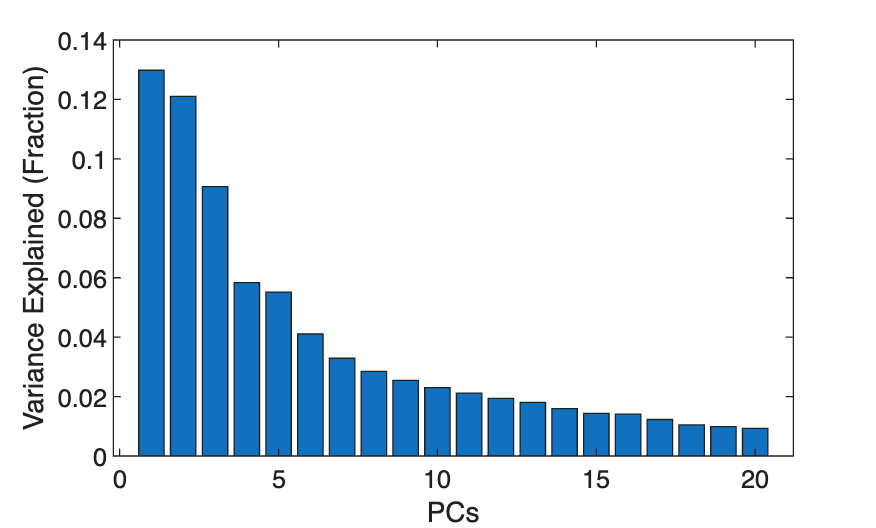

% Part A
X = reshape(mean_firing_rate, nTimeBins * nConditions, nUnits);

column_range  = max(X) - min(X);         
normalizer = column_range + 5;     
X_normalized = X ./ normalizer; 

[coeff, scores, latent] = pca(X_normalized);
nDims = 6;
coeff = coeff(:,  1:nDims);
scores = scores(:, 1:nDims);  

frac_var = latent / sum(latent); 
nPlotDims = 20;
figure;
bar(1:nPlotDims, frac_var(1:nPlotDims));
xlabel('PCs')
ylabel('Variance Explained (Fraction)')

In this plot, there is not an elbow. Instead, there is a more smooth decay. 

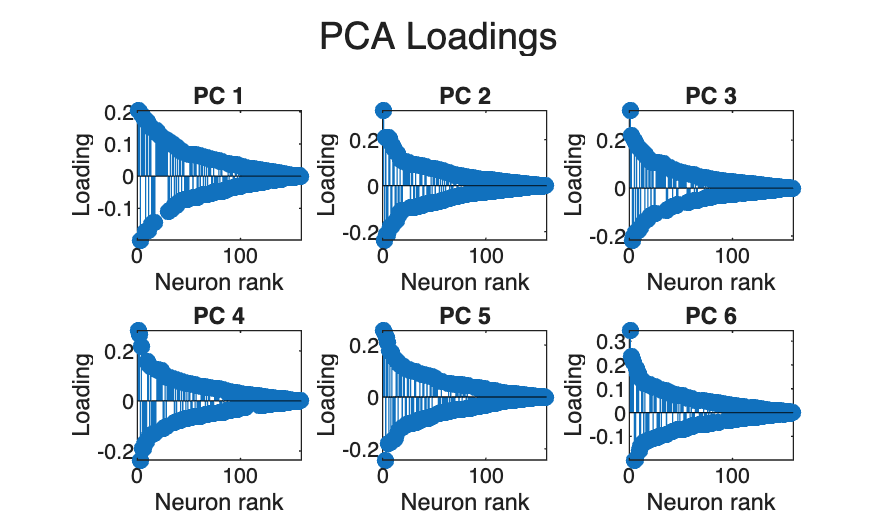

% Part B
figure; 
for d = 1:nDims
    subplot(2, 3, d);
 
    dim_coeff = coeff(:, d);      
    [~, sort_idx] = sort(abs(dim_coeff), 'descend');
    sorted_coeff  = dim_coeff(sort_idx);
 
    stem(1:nUnits, sorted_coeff, 'filled');
 
    xlabel('Neuron rank');
    ylabel('Loading');
    title(sprintf('PC %d', d));
    xlim([0 nUnits + 1]);
    yline(0, 'k-', 'LineWidth', 0.5);
end
 
sgtitle('PCA Loadings');

The loadings look dense with a smooth gradiation. There are some outliers, like in PC2 and PC3, where there are individual points that don't follow along the curve of the stem plot smoothly. This is because PCA captures the most variance of our data of all of our neurons, and variance is spread across the whole population. Therefore, PCA will find a solution that includes most of the variance and does not zero out most of the neurons, which would have lead to a more sparse representation. 

% Part C
nTrials = size(spike_counts_smooth, 2);
X_trials = reshape(spike_counts_smooth, nTimeBins * nTrials, nUnits);
X_trials = X_trials * (1000 / binSize);

X_trials_norm = X_trials ./ normalizer;
[coeff_trial, scores_trial, latent_trial] = pca(X_trials_norm);
coeff_trial = coeff_trial(:, 1:nDims);

% Part D
[Lambda, ~, ~] = factoran(X_trials_norm, nDims);
fprintf('Factor Analysis done. Lambda size: %d x %d\n', size(Lambda));

Factor Analysis done. Lambda size: 158 x 6



% Part E
angles_avg_trial = subspacea(coeff, coeff_trial); 
angles_avg_fa = subspacea(coeff, Lambda);  
angles_trial_fa = subspacea(coeff_trial, Lambda);   

angles_avg_trial_deg = rad2deg(angles_avg_trial);
angles_avg_fa_deg = rad2deg(angles_avg_fa);
angles_trial_fa_deg = rad2deg(angles_trial_fa);

fprintf('Principal angles (degrees):\n');

Principal angles (degrees):


fprintf('PCA-avg vs PCA-trial: %s\n', mat2str(round(angles_avg_trial_deg, 1)));

PCA-avg vs PCA-trial: [4.5;5.6;11.7;15.1;24.6;85.9]


fprintf('PCA-avg vs FA: %s\n', mat2str(round(angles_avg_fa_deg, 1)));

PCA-avg vs FA: [10.8;12.3;14.7;15.4;16.8;19.8]


fprintf('PCA-trial vs FA: %s\n', mat2str(round(angles_trial_fa_deg, 1)));

PCA-trial vs FA: [15.9;17.7;20;23.5;33.9;84.5]


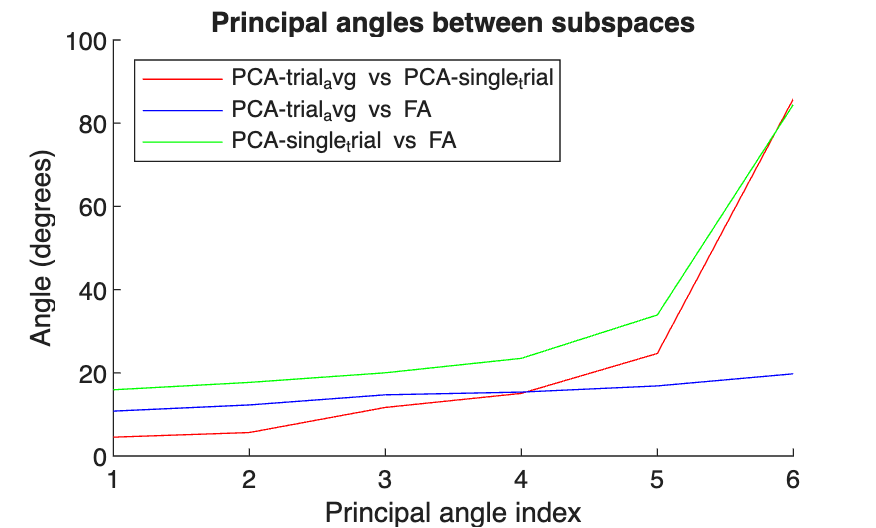


figure;
hold on

x = 1:nDims;
plot(x, angles_avg_trial_deg, 'r-','DisplayName', 'PCA-trial_avg vs PCA-single_trial');
plot(x, angles_avg_fa_deg,    'b-', 'DisplayName', 'PCA-trial_avg vs FA');
plot(x, angles_trial_fa_deg,  'g-', 'DisplayName', 'PCA-single_trial vs FA');

xlabel('Principal angle index');
ylabel('Angle (degrees)');
title('Principal angles between subspaces');
legend('Location', 'northwest');
xticks(1:nDims);

PCA trial averaged and PCA single trial look the most similar according to the plot. This is also shown in the angles as they have the closest angles to each other, meaning that the dimensions are shared between the two spaces. They are similar because PCA is being performed on the same task, which keeps the same axes of most variance. Trial averaging just reduces noise before performing PCA. 